# Distribution of the noise variance

For linear regression, an estimate of the noise variance is


$$\hat{\sigma}^2 = \frac{RSS}{n-(d+1)}$$


where RSS is the residual sum of squares, $n$ is the size of the sample, and we have $d+1$ regression weights. But what is the *distribution* of the noise variance?

As an easy knowledge check, what is the mean of this distribution? What is the domain of this distribution?

The above point estimate of the noise variance is correct for any distribution of the noise (including a biased one!). We can say something about the noise variance distribution if we assume a noise distribution. Let's assume the noise distribution is Gaussian.

For a Gaussian noise distribution, we know that


$$\frac{RSS}{\sigma^2} \sim \chi^2_{n-(d+1)}$$


but this is the distribution of the scaled RSS, and is not quite what we want.

Scaling a random variable that follows a certain distribution results in a new random variable that follows the same distribution with its width scaled. The height is also scaled so that the integral of the distribution remains 1.

Therefore,

$\frac{RSS}{n-(d+1)} = \frac{RSS}{\sigma^2} \cdot \frac{\sigma^2}{n-(d+1)}$.

The first factor on the right-hand side follows $\chi^2_{n-(d+1)}$, which we denote as $f_{n-(d+1)}(x)$, where $x$ is an element of the distribution. The scaled random variable $\frac{RSS}{n-(d+1)}$ then follows the probability distribution

$\left( \frac{n-(d+1)}{\sigma^2} \right) f_{n-(d+1)} \left( \frac{n-(d+1)}{\sigma^2} \cdot x \right)$.

We expect the mean of this distribution to be $\sigma^2$, and indeed it is, because the $f_{n-(d+1)}(x)$ has mean $n-(d+1)$, and the scaled distribution has the mean divided by $n-(d+1)$ and multipled by $\sigma^2$.

Let's plot this distribution for simple linear regression ($d=1$) with $n=5$ observations and a noise variance (which is typically unknown) of $\sigma^2=0.1$.

vari = 0.1;      % noise variance
dofs = 3;        % degrees of freedom: 5-(1+1)
sc = dofs/vari;  % scaling factor
xx = 0:0.01:0.5; % points at which we will plot the distribution
yy = sc*chi2pdf(xx*sc, dofs);
clf; plot(xx, yy); hold on

The mean of this distribution is located at 0.1. Is the peak of the distribution where we expect it to be? If the number of degrees of freedom is at least 2, then the peak of $f_{n-(d+1)}(x)$ is at $n-(d+1)-2$ (the peak is to the left of the mean). For the scaled distribution, to find the location of the peak, we divide $n-(d+1)-2$ by $n-(d+1)$ and multiply by $\sigma^2$. For our example, the peak is at

peak = (dofs-2)/dofs*vari

peak = 0.0333

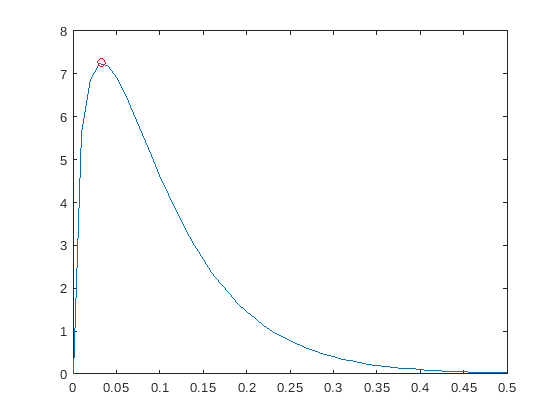

plot(peak, sc*chi2pdf(peak*sc, dofs), 'ro'); % plot point at peak

### Simulating the noise distribution

We can check our answer by simulating the noise distribution. We'll solve the least squares problems a large number of times, and each time we will estimate the noise variance. We will plot these noise variances in a histogram to see how the noise variance is distributed.

The ground truth model is this linear model.

w0 = 2;
w1 = 1;
fun = @(x) w0 + w1*x;

Loop over a very large number of samples.

n = 5;            % sample size
x = (1:n)';       % location of data
X = [ones(n,1) x];% least squares matrix
vari = 0.1;       % noise variance
ns = 1000000;     % number of samples
S2 = zeros(ns,1); % array storing estimates
for i = 1:ns
    u = randn(n,1)*sqrt(vari);
    y = fun(x) + u;
    w = X\y;              % least squares solution
    r = y - X*w;          % residual
    S2(i) = (r'*r)/(n-2); % estimate of noise variance
end

Now plot the normalized histogram of S2.

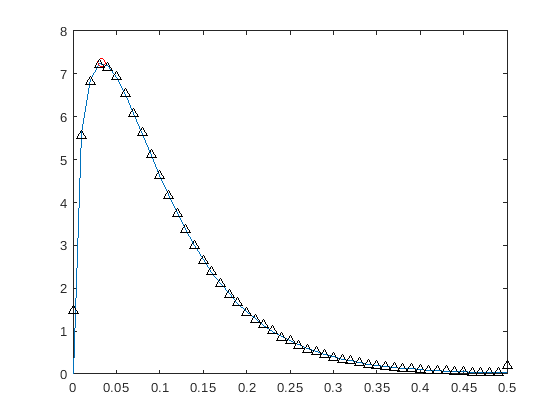

sp = 0.01;            % histogram bin spacing
c = 0:sp:0.5;         % histogram bin centers
f = hist(S2,c)/ns/sp; % normalized frequences of each bin
plot(c, f, 'k^');

### Other noise estimates and their distributions

In practice, we do not know what are the actual values of the noise $u_i$ in each observation $y_i$. If we did, we could easily obtain estimates of the noise variance using


$$\frac{1}{n-1} \sum_{i=1}^n (u_i - \bar{u})^2$$


or


$$\frac{1}{n} \sum_{i=1}^n u_i^2$$


with the latter assuming that the noise variance has mean 0. It is interesting to note that for a given sample of noise, $u_1,\ldots,u_n$, the three estimates of the noise variance, $\hat{\sigma}^2$ and the two here, are different.

To find the distributions of these two latter estimates, let us assume that the $u_i$ come from a Gaussian distribution with mean 0. From our chi-squared distribution demo, the first of the two estimates above follows a scaled chi-squared distribution with $n-1$ degrees of freedom. The second estimate follows a chi-squared distribution with $n$ degrees of freedom. Let us plot these two distributions, along with the distribution of the estimate based on RSS.

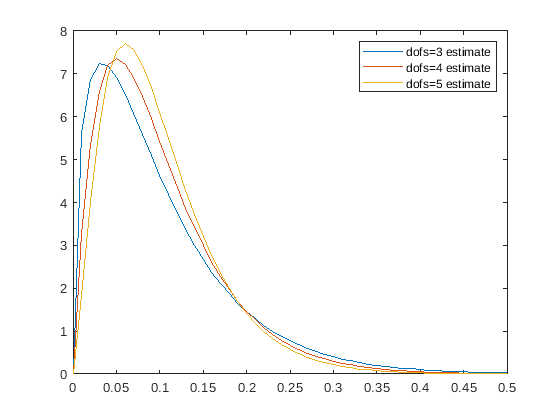

figure
xx = 0:0.01:0.5;
sc = 3/vari;
yy = sc*chi2pdf(xx*sc,3);
plot(xx, yy); hold on
sc = 4/vari;
yy = sc*chi2pdf(xx*sc,4);
plot(xx, yy);
sc = 5/vari;
yy = sc*chi2pdf(xx*sc,5);
plot(xx, yy);
legend('dofs=3 estimate', 'dofs=4 estimate', 'dofs=5 estimate');

These estimates all have the same mean, `vari` = 0.1, as they must. However, they have different peaks! The distribution of the estimate using 5 dofs is the most narrow; in a sense, it uses more information, e.g., the zero mean of the noise distribution is used explicitly.

### Taking it further

Perform simulations and plot histograms to numerically verify the distributions of the two estimates of the noise variance based on knowing $u_i$. Where are the peaks of these distributions located?